# Convolution and LTI Systems

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build some familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and they will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

**Suggested Prework**

The script [ConvolutionBasics.mlx](matlab:open('ConvolutionBasics.mlx')) explores the basics of convolution in signal processing.

Linear convolution describes the relationship between three important signals for a common type of system:

- Input, $x\left(n\right)$ 

- Output, $y\left(n\right)$

- The system's response to a unit impulse signal, $h\left(n\right)$

Let us explore this relationship by considering a fairly simple "*system*".

## **The Moving Average Operation**

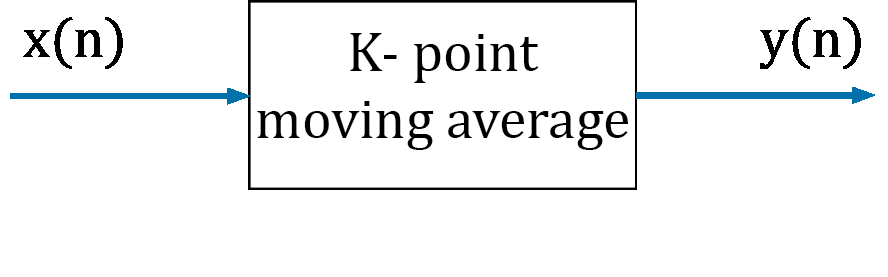

To compute a moving average, we use the [`movmean`](https://www.mathworks.com/help/matlab/ref/movmean.html) function. Visit the documentation to learn more about this syntax:

Let's define an arbitrary input signal for this system and compute the output.

  **Task.** Observe the input signal $x\left(n\right)$ and its 3000-point moving average$y\left(n\right)$.

figure("Position",[0 0 1000 350])
fprintf("The moving average system")
T = tiledlayout(1,2);
xlabel(T,"Time");
ylabel(T,"Amplitude")

Fs = 1000;                   % Sampling frequency
n  = -10:1/Fs:10;            % Discretized time 
K  = 3000;                   % Window length for moving average

% Input signal x(n) 
x = sinc(n);                 
nexttile;
plot(n,x,"LineWidth",1.8,SeriesIndex=1); 
lims = ylim();
title("Input signal x(n)")

% Moving average of input 
y = movmean(x,K,"Endpoints",0);
nexttile; 
plot(n,y,"LineWidth",1.8,SeriesIndex="none")
title("Output y(n) = Moving average of x(n)")

  **Task.** Replace the empty signal in the text box below to compute a 3000-point moving average of the unit impulse signal $\delta \left(n\right)$, that is, the variable `D`.

figure("Position",[0 0 1000 350])
T = tiledlayout(1,2);
xlabel(T,"Time");
ylabel(T,"Amplitude")

% Unit impulse 
D = n == 0 ;            
nexttile;
plot(n,D,"LineWidth",1.8,SeriesIndex=1)
title("Unit impulse \delta(n)")

% Compute K-point moving average of unit impulse, where window length is 3000 and
% EndPoints are set to 0.
h = nan(size(D));  
nexttile;
plot(n,h,"LineWidth",1.8,SeriesIndex="none"); 
title("Output h(n) = Moving average of \delta(n)")

  **Task. **Replace the empty signal in the text box below to compute linear convolution of $h\left(n\right)$ with $x\left(n\right)$ using [conv](https://www.mathworks.com/help/matlab/ref/conv.html) function setting the shape option to `"same"`.

figure("Position",[0 0 1500 350])
T = tiledlayout(1,3);
xlabel(T,"Time");
ylabel(T,"Amplitude")

% Compute linear convolution of impulse response h with the input signal x
% and store result in w.
w = nan(size(x));

% Plot the signals.
nexttile;
plot(n,x,"LineWidth",1.8,SeriesIndex=1); 
title("Input signal x(n)")
nexttile;
plot(n,h,"LineWidth",1.8,SeriesIndex="none"); 
title("h(n) = Moving average of \delta(n)")
nexttile;
plot(n,w,"LineWidth",2,SeriesIndex=2)
title("Convolution of h(n) with x(n)")

***Reflect***

- *Do you notice any relationship between *$y\left(n\right)$* and the convolution output *$w\left(n\right)$*?*

- *What do you think the relationship, or lack of relationship, between the two signals means?*

## What are Linear Time-Invariant Systems?

The moving average operation is an example of a special type of systems known as **linear time-invariant Systems (LTI)**. What does it mean for a system to be linear and time-invariant? 

  **Task. **Run this section of code. Observe and compare the plots.

Fs = 1000;                   % Sampling frequency
n = -10:1/Fs:10;             % Discretized time 
L = 3000;                    % Window length for moving average

Let us define two input signals. Use the drop-down to switch between different signals.

x1 = tripuls(n, 5);
x2 = sinc(n);

Use the sliders to choose the number of points to shift the input signals by. See [circshift](https://www.mathworks.com/help/matlab/ref/circshift.html) for more information.

x1 = circshift(x1,0) ;
x2 = circshift(x2,0) ;

Use the sliders below to set amplitude scale for the two input signals.

a1 = 1;
a2 = 1;

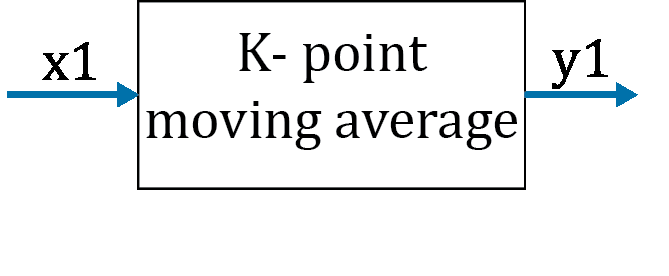              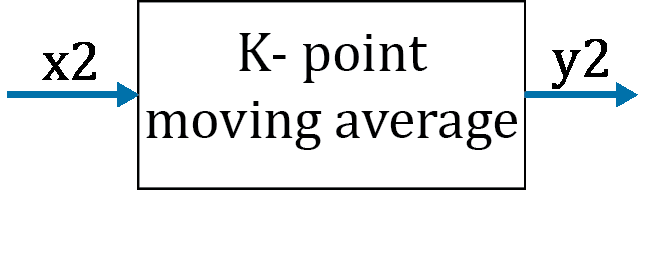

Compute the moving average of the sum of the scaled signals.                                                                 

ysumx = movmean(a1*x1 + a2*x2,L);

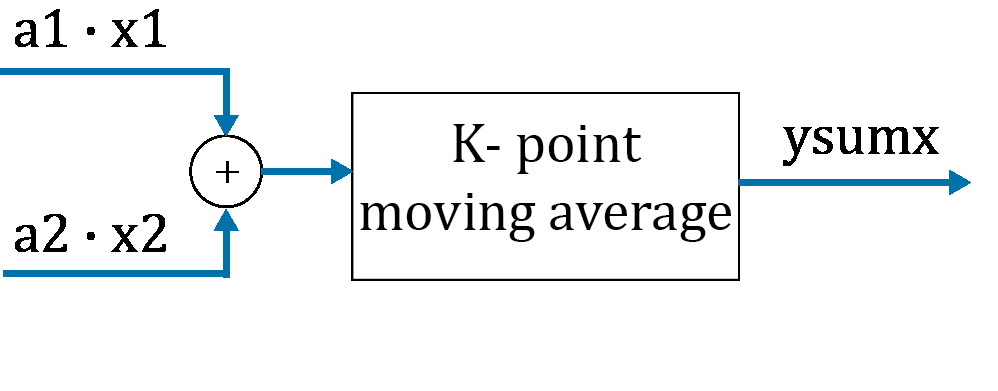

Compute the sum of scaled moving averages of `x1` and `x2`.

ysum = a1*movmean(x1,L) + a2*movmean(x2,L);

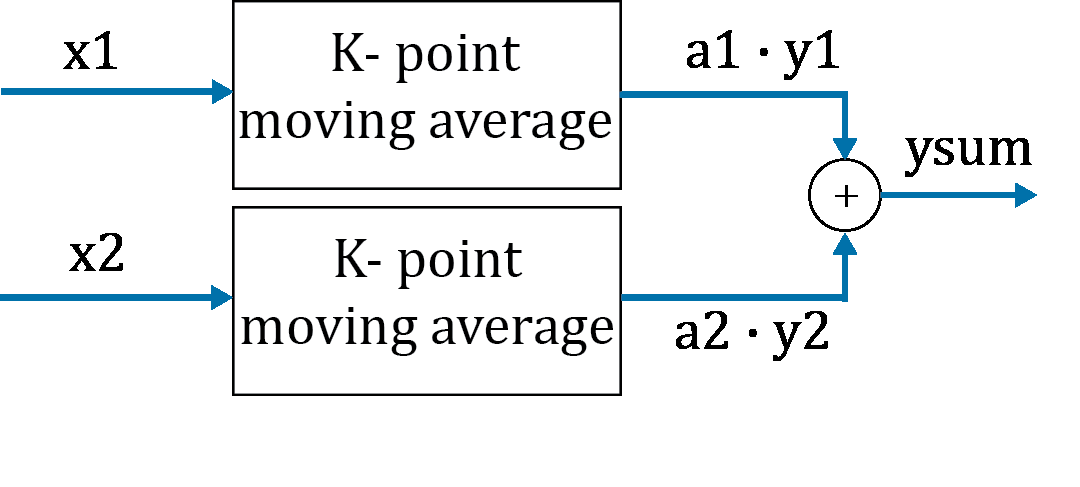

% Visualize the signals using a helper function provided at the end.
VisualizeLTI(n,[x1; x2],ysumx,ysum)

  **Try**

- Scale $\textrm{x1}$ by 5 and $\textrm{x2}$ by 10.

- Shift $\textrm{x1}$ 1000 points to the right.

- Shift $\textrm{x2}$ 500 points to the left.

- Define and include a third signal $\textrm{x3}$ of your choice.

***Reflect***

- *Compare the sum of moving average of the input signals with the moving average of their sum.*

- *What happens when you scale, shift, and/or change the input signals? Are *`ysumx`* and *`ysum`* always equivalent?*

- *What does it mean for a system to be linear and time-invariant?*

## Output of an LTI System

The following convolution relationship holds true for all linear and time-invariant systems or LTI systems.

                            
$$\mathrm{y}\left(\mathrm{n}\right)=\mathrm{x}\left(\mathrm{n}\right)\star \mathrm{h}\left(\mathrm{n}\right)$$


 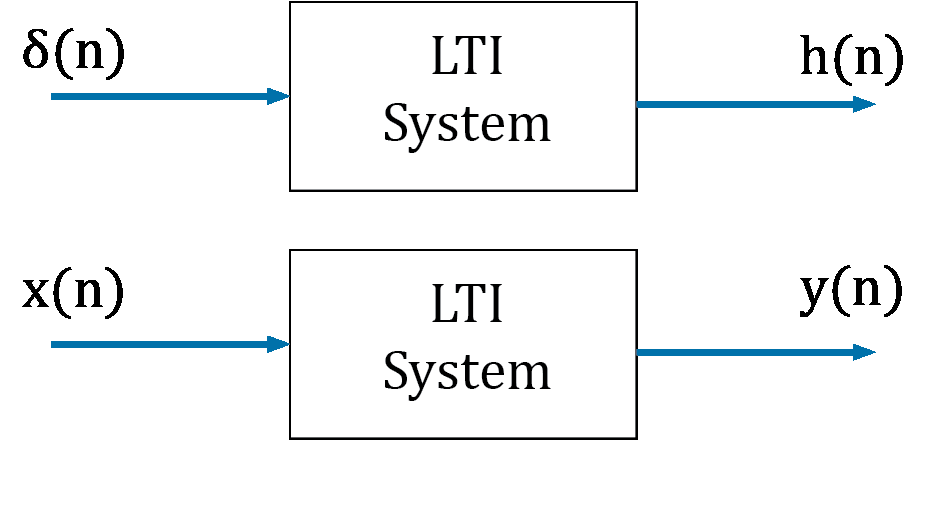      

In the first section, you verified this relationship for a known LTI system - *the moving average operation*. What if we have a much more complex system? For instance, the effect of sound reverberating in a room.

**NOTE:** Running this section will play an audio.

  **Task.** Read the text and code given below, run this section, and listen to the sound files being played.

Let's import a recording of an impulse sound signal reverberated from a church balcony.

[h, Fh] = audioread("1st_baptist_nashville_balcony.wav");            % Impulse response of the system
disp(size(h))   

The audio file *1st_baptist_nashville_balcony.wav* by Adam Townsell is licensed under [CC-BY](https://creativecommons.org/licenses/by/4.0/) and was obtained from [https://openairlib.net/](https://www.openair.hosted.york.ac.uk/?page_id=406). 

Notice that this audio has two channels (left and right). It is a stereophonic sound. Let's play this audio.

soundsc(h,Fh)                                    % Play the sound

      288000           2



pause(length(h)/Fh)                              % Wait for audio to finish playing

Let's import an anechoic sound to which we want to apply the same reverberation effect.

[x, Fx] = audioread("ringtone.wav");         % Read input     
disp(size(x))

Notice that this file has just one channel. It is a monophonic recording. Let's play it.

soundsc(x,Fx)                                % Play the sound
pause(length(x)/Fx)                          % Wait for audio to finish playing

      111616           1



  **Task.** Replace the empty signals in the text boxes below to compute linear convolution of $h_1 \left(n\right)$ and $h_2 \left(n\right)$ with $x\left(n\right)$using the [conv](https://www.mathworks.com/help/matlab/ref/conv.html) function, concatenate the two outputs appropriately, and play the resulting sound using [soundsc](https://www.mathworks.com/help/matlab/ref/soundsc.html).

h1 = h(:,1);                                % Extract the first channel from the impulse response
h2 = h(:,2);                                % Extract the second channel from the impulse response
y1 = nan(1);                  
y2 = nan(1);
y = nan(1);                    % Concatenate the two output channels
                          % Play the sound
pause(length(y)/Fx)                          % Wait for audio to finish playing

  **Try**

- Apply this effect to your own sound files!

- Compute the linear convolution result via circular convolution [cconv](https://www.mathworks.com/help/signal/ref/cconv.html) or via [fft](https://www.mathworks.com/help/matlab/ref/fft.html) instead.

- Plot the audio signals.

## **Practice Problem**

Given the impulse response of an unknown LTI system, compute its output for an arbitrary input.

Fs = 1000;                   % Sampling frequency
n = -5:1/Fs:5;               % Discretized time 

Get the impulse response of an unknown LTI System using the helper function `getImpulseResponse.`

h = GetImpulseResponse(n,Fs);

  **Task.** Replace the empty signal in the text box to compute the output for an input sequence `x.`

  **Pro-tip**. Use the command `conv(signal1,signal2,'same')` to return a result of the same size as the input signals, without the leading and trailing zeros. 

x = sinc(n);   % Input
y = conv(x,h,'same');   % Output of LTI system

  **Task. **Plot the input `x` and output `y` as functions of time. Replace the empty signals in text box with appropriate variables to plot the output.

figure;
plot(n,x,":","LineWidth",1.5,SeriesIndex="none");             % Input signal plot
hold on
plot(nan(size(n)),nan(size(n)),SeriesIndex=1) % Output signal plot
hold off
xlim([-4.99 4.99])
xlabel("Time");
ylabel("Amplitude")
legend("Input","Output")

** Task.**

- Change `x` to different signals using the drop-down.

- Based on your observations, what operation do you think this LTI system is performing on the input? 

- Change the x-axis limits to `[-5 5]`. What do you notice? **Hint**: Change `x` to `exp(n)`

- Examine the last two values of `y` when` x = exp(n)`. If you notice something strange near the end of the signal, can you explain what might be causing this?

Upon completion, the output of the system for sinc signal should look like this:

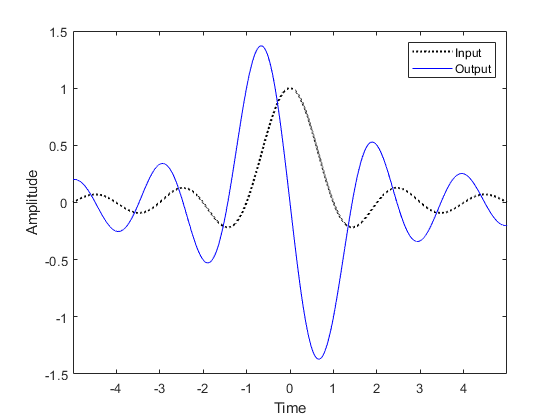

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

## **Helper Functions**

Function to visualize input signals and results of passing their linear combination to an LTI system.

function VisualizeLTI(n,X,ysumx,ysum)
% VISUALIZELTI(N,X,YSUMX,YSUM) creates the different outputs to demonstrate
% linearity and time invariance.

% Visualize the individual inputs
K = size(X,1);
figure("Position",[0 0 1000 350]);
T = tiledlayout(1,K,"TileSpacing","compact");
xlabel(T,"Time");
ylabel(T,"Amplitude")

for k = 1:K
    nexttile
    plot(n,X(k,:),"-","LineWidth",1.8,SeriesIndex=1)
    title("Input x" + k)
end

% Visualize sum of individual moving averages vs a moving average of the sum
figure("Position",[0 0 1000 350]);
t = tiledlayout(2,1,"TileSpacing","compact");
xlabel(t,"Time");
ylabel(t,"Amplitude")
nexttile;
plot(n,ysumx,"LineWidth",1.8,SeriesIndex=2)
title("\fontsize{12}Moving average of input sum")
nexttile;
plot(n,ysum,"LineWidth",1.8,SeriesIndex="none")
title("\fontsize{12}Sum of input moving averages")

end


Function for an "unknown" LTI system.

function h = GetImpulseResponse(n,fs)
% GETIMPUSLSERESPONSE(N,FS) generates an impulse response corresponding to
% an LTI system (derivative).

D = n == 0;      % Impulse signal
D(end+1) = 0;    
h = diff(D)*fs;

end
